iterations = 10;
time_IRWA_20 = 0;
time_ADMM_20 = 0;
time_baseline_20 = 0;


for i = 1:iterations
    [H, g, A1, A2, b1, b2] = generate_random_qp(20,5,3);
    tic;
    x = QP_scaling_1(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_IRWA_20 = time_IRWA_20 + elapsedTime;
    
    tic;
    x = ADMM_QP(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_ADMM_20 = time_ADMM_20 + elapsedTime;
    
    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    tic;
    results = m.solve();
    x = results.x
    elapsedTime = toc; 
    time_baseline_20 = time_baseline_20 + elapsedTime;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -4.7014e-01   2.33e+00   1.17e+03   1.00e-01   2.50e-04s
  50   2.4355e+00   1.46e-09   1.58e-08   1.00e-01   5.59e-04s

status:               solved
number of iterations: 50
optimal objective:    2.4355
run time:             8.20e-04s
optimal rho estimate: 4.70e-02



x =     0.2243
    0.2793
    0.2345
   -0.0499
   -0.4184
   -0.2398
   -0.2103
    0.0633
   -0.1761
   -0.1289


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.1596e-01   1.96e+00   2.01e+03   1.00e-01   2.67e-04s
  50   7.1394e+00   2.73e-09   2.65e-08   1.00e-01   5.82e-04s

status:               solved
number of iterations: 50
optimal objective:    7.1394
run time:             8.74e-04s
optimal rho estimate: 6.86e-02



x =     0.0049
   -0.5662
    0.2686
    1.0708
    0.2590
   -0.4541
    0.0366
   -0.5084
   -0.1352
    0.1948


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.2636e-01   2.10e+00   1.77e+03   1.00e-01   3.05e-04s
  50   5.1987e-01   3.23e-09   2.40e-08   1.00e-01   6.52e-04s

status:               solved
number of iterations: 50
optimal objective:    0.5199
run time:             9.13e-04s
optimal rho estimate: 4.27e-02



x =     0.3740
   -0.2190
    0.3255
   -0.4015
    0.2044
    0.1106
    0.4651
   -0.1136
    0.7232
    0.5212


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.2133e-01   2.29e+00   2.37e+03   1.00e-01   2.63e-04s
  50   1.7730e+00   3.79e-09   3.19e-08   1.00e-01   5.89e-04s

status:               solved
number of iterations: 50
optimal objective:    1.7730
run time:             8.47e-04s
optimal rho estimate: 5.08e-02



x =    -0.1450
   -0.1012
    0.1292
    0.1426
   -0.3430
    0.2814
   -0.0903
    0.4688
   -0.2804
   -0.0373


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.2307e-01   2.08e+00   2.95e+03   1.00e-01   2.81e-04s
  50   2.6345e+00   3.27e-09   3.63e-08   1.00e-01   6.00e-04s

status:               solved
number of iterations: 50
optimal objective:    2.6345
run time:             8.86e-04s
optimal rho estimate: 3.95e-02



x =     0.3284
   -0.2884
   -0.0602
   -0.3797
   -0.0271
    0.0085
    0.0945
    0.0754
   -0.0759
    0.0207


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -2.6107e-01   1.26e+00   2.16e+03   1.00e-01   2.45e-04s
  50   1.6937e+00   1.98e-09   2.65e-08   1.00e-01   5.58e-04s

status:               solved
number of iterations: 50
optimal objective:    1.6937
run time:             8.19e-04s
optimal rho estimate: 5.36e-02



x =    -0.1508
   -0.3044
    0.4712
    0.0818
   -0.2747
    0.1009
   -0.1814
   -0.0139
    0.1446
    0.2734


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -1.3234e+00   2.39e+00   3.78e+03   1.00e-01   2.53e-04s
  75   8.1053e+00   4.41e-13   4.00e-11   6.48e+00   6.41e-04s

status:               solved
number of iterations: 75
optimal objective:    8.1053
run time:             9.55e-04s
optimal rho estimate: 1.08e+00



x =    -0.0825
   -0.4148
    0.6863
    0.6994
   -0.0822
   -0.1886
   -0.5070
   -0.0752
   -0.6444
   -0.2439


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.8476e-01   1.68e+00   2.20e+03   1.00e-01   2.57e-04s
  50   1.2826e+00   3.13e-09   2.83e-08   1.00e-01   5.98e-04s

status:               solved
number of iterations: 50
optimal objective:    1.2826
run time:             9.38e-04s
optimal rho estimate: 5.78e-02



x =    -0.3039
   -0.4382
   -0.2818
   -0.0456
   -0.1453
    0.1364
   -0.0131
    0.3040
    0.0416
   -0.1181


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -4.9544e-01   1.47e+00   1.59e+03   1.00e-01   2.66e-04s
  50  -6.6170e-04   1.74e-09   2.13e-08   1.00e-01   6.12e-04s

status:               solved
number of iterations: 50
optimal objective:    -0.0007
run time:             8.98e-04s
optimal rho estimate: 5.03e-02



x =     0.2398
   -0.1770
    0.3982
   -0.0089
    0.0537
   -0.0338
    0.2614
    0.2415
   -0.1192
    0.4298


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -9.5788e-01   1.85e+00   1.84e+03   1.00e-01   2.68e-04s
  50  -2.5195e-01   3.10e-09   2.45e-08   1.00e-01   6.09e-04s

status:               solved
number of iterations: 50
optimal objective:    -0.2520
run time:             8.89e-04s
optimal rho estimate: 4.00e-02



x =     0.6195
   -0.1846
    0.1050
   -0.0458
   -0.2475
   -0.4355
    0.3251
   -0.0693
    0.1608
    0.4970



time_ADMM_20 = time_ADMM_20 / iterations;
time_IRWA_20 = time_IRWA_20 / iterations;
time_baseline_20 = time_baseline_20 / iterations;


time_IRWA_50 = 0;
time_ADMM_50 = 0;
time_baseline_50 = 0;

for i = 1:iterations
    [H, g, A1, A2, b1, b2] = generate_random_qp(50,10,10);
    tic;
    x = QP_scaling_1(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_IRWA_50 = time_IRWA_50 + elapsedTime;
    
    tic;
    x = ADMM_QP(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_ADMM_50 = time_ADMM_50 + elapsedTime;

    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    tic;
    results = m.solve();
    x = results.x
    elapsedTime = toc; 
    time_baseline_50 = time_baseline_50 + elapsedTime;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.5066e-01   2.28e+00   6.88e+03   1.00e-01   6.26e-04s
  50   7.5984e+00   4.07e-09   9.24e-08   1.00e-01   1.29e-03s

status:               solved
number of iterations: 50
optimal objective:    7.5984
run time:             1.60e-03s
optimal rho estimate: 4.11e-02



x =     0.1702
    0.3232
    0.2901
    0.0696
    0.1497
    0.2503
    0.4869
   -0.1657
    0.1964
   -0.1032


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -1.2117e+00   1.51e+00   8.95e+03   1.00e-01   7.07e-04s
  50   2.1773e-01   7.97e-09   1.18e-07   1.98e-02   1.47e-03s

status:               solved
number of iterations: 50
optimal objective:    0.2177
run time:             1.80e-03s
optimal rho estimate: 9.51e-03



x =    -0.0578
   -0.0849
   -0.0681
   -0.0276
    0.1011
    0.1031
    0.1077
    0.1615
   -0.0419
   -0.2931


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.7598e-01   2.22e+00   8.53e+03   1.00e-01   6.82e-04s
  50   3.9238e+00   3.83e-09   1.15e-07   1.00e-01   1.39e-03s

status:               solved
number of iterations: 50
optimal objective:    3.9238
run time:             1.73e-03s
optimal rho estimate: 3.56e-02



x =    -0.0319
   -0.3226
    0.0533
   -0.0302
    0.0018
   -0.0780
    0.1774
   -0.0496
    0.1819
    0.0065


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.2858e-01   1.99e+00   4.38e+03   1.00e-01   6.57e-04s
  50   1.3083e+00   2.34e-09   5.81e-08   1.00e-01   1.29e-03s

status:               solved
number of iterations: 50
optimal objective:    1.3083
run time:             1.61e-03s
optimal rho estimate: 3.34e-02



x =    -0.0926
   -0.0728
    0.0989
    0.0237
    0.1175
   -0.1417
   -0.0496
    0.0175
    0.0853
    0.1372


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.2499e-01   3.21e+00   8.00e+03   1.00e-01   6.61e-04s
  50   1.1207e+01   4.31e-09   1.07e-07   1.00e-01   1.27e-03s

status:               solved
number of iterations: 50
optimal objective:    11.2067
run time:             1.58e-03s
optimal rho estimate: 3.40e-02



x =     0.0030
   -0.0011
   -0.1132
    0.0901
   -0.0893
    0.2432
    0.4642
   -0.0173
    0.1233
   -0.0207


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.2033e-01   1.54e+00   4.27e+03   1.00e-01   6.05e-04s
  50   2.1641e+00   2.64e-09   5.71e-08   1.00e-01   1.22e-03s

status:               solved
number of iterations: 50
optimal objective:    2.1641
run time:             1.53e-03s
optimal rho estimate: 3.54e-02



x =     0.1350
   -0.0200
    0.1074
    0.0881
   -0.0035
   -0.1116
   -0.1738
   -0.0189
    0.1388
   -0.0557


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.3327e-01   1.60e+00   6.70e+03   1.00e-01   6.03e-04s
  50   2.7143e+00   2.79e-09   9.13e-08   1.00e-01   1.21e-03s

status:               solved
number of iterations: 50
optimal objective:    2.7143
run time:             1.51e-03s
optimal rho estimate: 4.19e-02



x =     0.0434
   -0.0844
   -0.1574
   -0.0250
   -0.0132
    0.1005
   -0.0461
   -0.1729
    0.1315
   -0.1007


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -1.0946e+00   1.63e+00   7.59e+03   1.00e-01   6.43e-04s
  50   2.0231e+00   3.18e-09   1.02e-07   1.00e-01   1.31e-03s

status:               solved
number of iterations: 50
optimal objective:    2.0231
run time:             1.68e-03s
optimal rho estimate: 3.22e-02



x =     0.0079
    0.1330
    0.1995
   -0.0367
   -0.1775
    0.1269
    0.2067
    0.1294
   -0.1617
    0.1401


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -9.6208e-01   1.89e+00   2.81e+03   1.00e-01   6.56e-04s
  50   3.8380e-01   1.80e-09   4.34e-08   1.00e-01   1.35e-03s

status:               solved
number of iterations: 50
optimal objective:    0.3838
run time:             1.70e-03s
optimal rho estimate: 3.61e-02



x =    -0.1689
    0.0342
    0.0842
   -0.0105
   -0.2387
    0.1124
   -0.0170
    0.0028
    0.0784
    0.2295


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.8998e-01   1.83e+00   6.81e+03   1.00e-01   6.12e-04s
  50   3.0041e+00   1.94e-07   8.78e-08   1.96e-02   1.35e-03s

status:               solved
number of iterations: 50
optimal objective:    3.0041
run time:             1.65e-03s
optimal rho estimate: 4.60e-02



x =    -0.0562
   -0.0107
   -0.0318
   -0.1470
   -0.0510
    0.0616
    0.0005
   -0.1981
   -0.0131
   -0.0612



time_ADMM_50 = time_ADMM_50 / iterations;
time_IRWA_50 = time_IRWA_50 / iterations;
time_baseline_50 = time_baseline_50 / iterations;

time_IRWA_100 = 0;
time_ADMM_100 = 0;
time_baseline_100 = 0;


for i = 1:iterations
    [H, g, A1, A2, b1, b2] = generate_random_qp(100,20,20);
    tic;
    x = QP_scaling_1(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_IRWA_100 = time_IRWA_100 + elapsedTime;
    
    tic;
    x = ADMM_QP(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_ADMM_100 = time_ADMM_100 + elapsedTime;

    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    tic;
    results = m.solve();
    x = results.x
    elapsedTime = toc; 
    time_baseline_100 = time_baseline_100 + elapsedTime;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -1.0892e+00   2.98e+00   9.87e+03   1.00e-01   2.34e-03s
  50   3.1270e+00   5.18e-08   1.20e-07   1.59e-02   4.16e-03s

status:               solved
number of iterations: 50
optimal objective:    3.1270
run time:             4.51e-03s
optimal rho estimate: 1.45e-02



x =    -0.1385
   -0.0463
    0.2010
    0.0459
    0.0522
    0.1286
   -0.0390
    0.0069
    0.0018
    0.1084


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.6978e-01   2.47e+00   1.74e+04   1.00e-01   2.23e-03s
  50   8.8180e+00   1.66e-07   2.24e-07   1.95e-02   4.03e-03s

status:               solved
number of iterations: 50
optimal objective:    8.8180
run time:             4.35e-03s
optimal rho estimate: 2.81e-02



x =    -0.1885
   -0.1559
    0.1082
   -0.1594
   -0.1045
   -0.2013
   -0.1262
    0.0152
    0.1943
   -0.0756


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.6305e-01   1.74e+00   1.18e+04   1.00e-01   2.33e-03s
  50   4.5447e+00   8.83e-09   1.59e-07   1.89e-02   4.21e-03s

status:               solved
number of iterations: 50
optimal objective:    4.5447
run time:             4.53e-03s
optimal rho estimate: 8.87e-03



x =    -0.0201
   -0.0640
    0.0586
   -0.1034
   -0.0093
   -0.1864
   -0.2246
    0.2357
   -0.1338
   -0.0589


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -9.2687e-01   1.33e+00   9.18e+03   1.00e-01   2.23e-03s
  75   8.0487e-01   5.46e-11   1.89e-09   9.09e-02   4.95e-03s

status:               solved
number of iterations: 75
optimal objective:    0.8049
run time:             5.28e-03s
optimal rho estimate: 2.66e-02



x =     0.0832
    0.0029
   -0.0722
   -0.0107
    0.1652
    0.0336
    0.0094
    0.0138
    0.0142
   -0.1695


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -1.3199e+00   1.81e+00   1.08e+04   1.00e-01   2.75e-03s
  50   3.9277e+00   8.84e-08   2.88e-06   1.00e-01   4.25e-03s

status:               solved
number of iterations: 50
optimal objective:    3.9277
run time:             4.58e-03s
optimal rho estimate: 3.18e-02



x =    -0.1967
   -0.0778
   -0.0581
    0.0424
   -0.0151
   -0.1156
    0.0480
   -0.0993
    0.0493
   -0.1545


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.4538e-01   2.17e+00   1.94e+04   1.00e-01   2.21e-03s
  50   7.6701e+00   1.32e-06   3.54e-07   1.27e-02   4.04e-03s

status:               solved
number of iterations: 50
optimal objective:    7.6701
run time:             4.47e-03s
optimal rho estimate: 4.05e-02



x =     0.0753
    0.0321
    0.0554
   -0.1010
   -0.0745
   -0.0684
   -0.0282
   -0.2212
    0.0965
   -0.0030


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -9.0711e-01   2.78e+00   1.64e+04   1.00e-01   2.34e-03s
  50   7.2838e+00   1.45e-08   2.17e-07   1.93e-02   4.33e-03s

status:               solved
number of iterations: 50
optimal objective:    7.2838
run time:             4.69e-03s
optimal rho estimate: 9.24e-03



x =    -0.1464
    0.0929
   -0.0261
    0.1017
    0.1083
   -0.1898
    0.0006
    0.0184
   -0.0975
   -0.0767


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.4759e-01   2.38e+00   2.18e+04   1.00e-01   2.57e-03s
  50   6.3908e+00   3.06e-07   2.75e-07   1.24e-02   4.65e-03s

status:               solved
number of iterations: 50
optimal objective:    6.3908
run time:             5.05e-03s
optimal rho estimate: 1.69e-02



x =     0.0753
   -0.2156
    0.0738
    0.0339
    0.1739
   -0.0041
    0.2439
   -0.2153
    0.0374
    0.0176


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.8600e-01   2.37e+00   1.81e+04   1.00e-01   2.43e-03s
  50   7.9464e+00   3.29e-08   2.52e-07   1.86e-02   4.41e-03s

status:               solved
number of iterations: 50
optimal objective:    7.9464
run time:             4.76e-03s
optimal rho estimate: 1.27e-02



x =     0.0819
    0.0523
    0.0947
    0.0096
   -0.1314
    0.0848
   -0.0740
    0.2655
   -0.1127
    0.2748


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.4827e-01   2.19e+00   1.89e+04   1.00e-01   2.28e-03s
  50   4.9428e+00   6.94e-07   2.73e-07   1.44e-02   4.14e-03s

status:               solved
number of iterations: 50
optimal objective:    4.9428
run time:             4.48e-03s
optimal rho estimate: 3.10e-02



x =    -0.0851
   -0.1852
   -0.0041
   -0.0977
   -0.0061
   -0.0318
   -0.1902
    0.2588
    0.0428
   -0.0136



time_ADMM_100 = time_ADMM_100 / iterations;
time_IRWA_100 = time_IRWA_100 / iterations;
time_baseline_100 = time_baseline_100 / iterations;



time_IRWA_200 = 0;
time_ADMM_200 = 0;
time_baseline_200 = 0;

for i = 1:iterations
    [H, g, A1, A2, b1, b2] = generate_random_qp(200,50,50);
    tic;
    x = QP_scaling_1(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_IRWA_200 = time_IRWA_200 + elapsedTime;
    
    tic;
    x = ADMM_QP(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_ADMM_200 = time_ADMM_200 + elapsedTime;

    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    tic;
    results = m.solve();
    x = results.x
    elapsedTime = toc; 
    time_baseline_200 = time_baseline_200 + elapsedTime;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.9626e-01   1.91e+00   4.54e+04   1.00e-01   1.71e-02s
  75   1.6050e+01   3.20e-09   3.33e-07   1.00e-01   2.74e-02s

status:               solved
number of iterations: 75
optimal objective:    16.0499
run time:             2.81e-02s
optimal rho estimate: 2.15e-02



x =    -0.1115
   -0.0440
   -0.0293
   -0.1081
   -0.0217
   -0.0569
    0.1826
    0.1311
    0.0479
   -0.0533


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.2595e-01   2.73e+00   4.21e+04   1.00e-01   1.64e-02s
  75   1.1205e+01   1.18e-07   3.75e-08   1.56e-02   3.13e-02s

status:               solved
number of iterations: 75
optimal objective:    11.2049
run time:             3.18e-02s
optimal rho estimate: 4.89e-02



x =     0.1338
    0.0363
   -0.0503
    0.1029
   -0.0435
   -0.0820
    0.0717
   -0.2181
    0.0999
   -0.0671


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.7771e-01   2.78e+00   4.53e+04   1.00e-01   1.58e-02s
  75   2.1204e+01   2.02e-08   8.47e-09   1.85e-02   3.09e-02s

status:               solved
number of iterations: 75
optimal objective:    21.2037
run time:             3.14e-02s
optimal rho estimate: 5.79e-02



x =    -0.1023
   -0.0461
   -0.0533
    0.0320
    0.0039
    0.0147
   -0.0333
   -0.0852
    0.0208
   -0.0707


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.3393e-01   2.36e+00   5.17e+04   1.00e-01   1.51e-02s
  75   2.2507e+01   2.92e-08   1.34e-08   1.66e-02   2.94e-02s

status:               solved
number of iterations: 75
optimal objective:    22.5072
run time:             3.00e-02s
optimal rho estimate: 4.71e-02



x =    -0.0115
   -0.0130
    0.0270
    0.0605
    0.0434
    0.1907
    0.0065
   -0.0353
    0.1408
   -0.0278


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.3519e-01   2.74e+00   3.92e+04   1.00e-01   1.54e-02s
  75   2.9314e+01   1.60e-08   3.33e-06   1.00e-01   2.41e-02s

status:               solved
number of iterations: 75
optimal objective:    29.3138
run time:             2.46e-02s
optimal rho estimate: 1.80e-02



x =     0.0571
   -0.0721
    0.0834
   -0.0716
   -0.0066
   -0.1222
    0.0233
    0.1022
    0.0832
   -0.0065


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.1595e-01   3.35e+00   4.21e+04   1.00e-01   1.39e-02s
  75   3.3474e+01   7.20e-10   6.50e-10   1.80e-02   2.70e-02s

status:               solved
number of iterations: 75
optimal objective:    33.4740
run time:             2.76e-02s
optimal rho estimate: 4.98e-02



x =    -0.0830
   -0.0273
   -0.0432
    0.0737
   -0.1564
    0.1374
   -0.1350
   -0.1139
    0.0177
    0.0522


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.0518e-01   2.26e+00   4.41e+04   1.00e-01   1.28e-02s
  75   1.8507e+01   3.00e-10   2.77e-10   1.86e-02   2.43e-02s

status:               solved
number of iterations: 75
optimal objective:    18.5066
run time:             2.46e-02s
optimal rho estimate: 4.38e-02



x =    -0.0258
    0.1365
   -0.0160
   -0.1284
    0.0573
   -0.0081
   -0.0877
    0.0901
    0.0266
    0.0226


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.6291e-01   2.60e+00   4.85e+04   1.00e-01   1.41e-02s
  75   1.9613e+01   7.34e-08   2.53e-08   1.49e-02   2.74e-02s

status:               solved
number of iterations: 75
optimal objective:    19.6128
run time:             2.80e-02s
optimal rho estimate: 4.53e-02



x =     0.0117
   -0.1108
    0.0481
    0.0250
    0.0617
    0.0330
    0.0753
    0.1172
   -0.2116
   -0.0625


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.1715e-01   1.77e+00   4.11e+04   1.00e-01   1.73e-02s
  75   7.2703e+00   2.92e-08   8.14e-09   1.19e-02   3.38e-02s

status:               solved
number of iterations: 75
optimal objective:    7.2703
run time:             3.44e-02s
optimal rho estimate: 4.77e-02



x =    -0.0407
   -0.0214
    0.0504
   -0.0566
   -0.1154
   -0.1175
   -0.1229
   -0.0551
    0.0377
   -0.1030


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 100
          nnz(P) + nnz(A) = 40100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.0259e-01   2.18e+00   5.35e+04   1.00e-01   1.55e-02s
  75   1.5910e+01   7.25e-09   3.58e-09   1.81e-02   2.95e-02s

status:               solved
number of iterations: 75
optimal objective:    15.9098
run time:             3.00e-02s
optimal rho estimate: 6.21e-02



x =    -0.0740
   -0.0714
    0.0194
    0.0301
    0.1206
    0.0617
    0.0857
    0.0786
   -0.0772
    0.0457



time_ADMM_200 = time_ADMM_200 / iterations;
time_IRWA_200 = time_IRWA_200 / iterations;
time_baseline_200 = time_baseline_200 / iterations;



time_IRWA_300 = 0;
time_ADMM_300 = 0;
time_baseline_300 = 0;


for i = 1:iterations
    [H, g, A1, A2, b1, b2] = generate_random_qp(300,60,60);
    tic;
    x = QP_scaling_1(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_IRWA_300 = time_IRWA_300 + elapsedTime;
    
    tic;
    x = ADMM_QP(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_ADMM_300 = time_ADMM_300 + elapsedTime;

    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    tic;
    results = m.solve();
    x = results.x
    elapsedTime = toc; 
    time_baseline_300 = time_baseline_300 + elapsedTime;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.6073e-01   2.10e+00   7.53e+04   1.00e-01   3.71e-02s
 125   2.1999e+01   3.60e-09   9.20e-10   9.42e-03   7.96e-02s

status:               solved
number of iterations: 125
optimal objective:    21.9992
run time:             8.02e-02s
optimal rho estimate: 3.53e-02



x =    -0.0022
   -0.1179
   -0.0316
    0.0129
   -0.1050
   -0.0274
    0.0647
    0.0474
   -0.0054
   -0.0857


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.1149e-01   2.60e+00   7.23e+04   1.00e-01   3.50e-02s
 125   1.7449e+01   1.06e-09   4.35e-10   1.05e-02   7.67e-02s

status:               solved
number of iterations: 125
optimal objective:    17.4492
run time:             7.72e-02s
optimal rho estimate: 3.19e-02



x =     0.0140
    0.1381
   -0.1126
   -0.0310
    0.0784
   -0.0370
    0.0005
   -0.0211
   -0.0251
    0.0421


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.7603e-01   2.68e+00   8.21e+04   1.00e-01   3.78e-02s
 125   2.8534e+01   3.81e-11   3.09e-11   1.13e-02   8.33e-02s

status:               solved
number of iterations: 125
optimal objective:    28.5344
run time:             8.40e-02s
optimal rho estimate: 2.86e-02



x =    -0.0028
    0.0512
    0.1092
   -0.0646
   -0.0370
   -0.0291
    0.0674
    0.0848
   -0.0527
    0.0424


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.8118e-01   2.51e+00   1.02e+05   1.00e-01   3.68e-02s
 125   1.2849e+01   3.36e-11   3.16e-11   1.24e-02   8.20e-02s

status:               solved
number of iterations: 125
optimal objective:    12.8493
run time:             8.27e-02s
optimal rho estimate: 2.89e-02



x =     0.0809
    0.0583
    0.1141
   -0.0730
   -0.0516
   -0.0325
   -0.0891
   -0.0703
    0.0834
   -0.0878


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.9732e-01   2.79e+00   7.28e+04   1.00e-01   3.29e-02s
 125   1.5939e+01   2.40e-09   2.08e-09   8.90e-03   7.27e-02s

status:               solved
number of iterations: 125
optimal objective:    15.9394
run time:             7.33e-02s
optimal rho estimate: 1.99e-02



x =    -0.0542
   -0.0123
    0.0614
   -0.1291
   -0.0501
   -0.0402
   -0.0339
   -0.0168
   -0.0705
    0.0130


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.3211e-01   2.38e+00   6.73e+04   1.00e-01   2.74e-02s
 125   1.2000e+01   9.08e-11   9.99e-11   1.19e-02   6.01e-02s

status:               solved
number of iterations: 125
optimal objective:    12.0000
run time:             6.06e-02s
optimal rho estimate: 2.71e-02



x =     0.0334
    0.0857
   -0.0268
   -0.0113
   -0.0634
    0.0195
   -0.0890
   -0.0077
    0.1253
   -0.0051


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -9.3071e-01   3.13e+00   7.49e+04   1.00e-01   2.90e-02s
 125   2.1173e+01   9.86e-09   3.99e-09   8.15e-03   6.43e-02s

status:               solved
number of iterations: 125
optimal objective:    21.1732
run time:             6.48e-02s
optimal rho estimate: 2.55e-02



x =     0.0009
    0.1820
    0.0367
    0.1672
    0.0260
   -0.1055
   -0.0460
   -0.1052
   -0.0717
    0.0301


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.2901e-01   2.57e+00   5.37e+04   1.00e-01   3.35e-02s
 125   1.2029e+01   1.15e-09   4.79e-10   6.89e-03   7.34e-02s

status:               solved
number of iterations: 125
optimal objective:    12.0287
run time:             7.39e-02s
optimal rho estimate: 2.06e-02



x =     0.0205
   -0.0313
   -0.0102
   -0.0103
    0.0602
    0.0923
    0.0226
    0.0193
   -0.0319
   -0.0001


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.9331e-01   3.14e+00   7.74e+04   1.00e-01   3.65e-02s
 125   2.8220e+01   1.61e-11   1.50e-11   1.42e-02   8.17e-02s

status:               solved
number of iterations: 125
optimal objective:    28.2205
run time:             8.24e-02s
optimal rho estimate: 3.46e-02



x =    -0.1075
   -0.0579
   -0.0347
    0.0716
    0.0889
    0.0887
    0.0677
   -0.0289
   -0.0974
    0.0248


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.9416e-01   2.73e+00   7.32e+04   1.00e-01   3.79e-02s
 125   1.5535e+01   1.49e-11   8.98e-12   9.59e-03   8.27e-02s

status:               solved
number of iterations: 125
optimal objective:    15.5354
run time:             8.33e-02s
optimal rho estimate: 2.37e-02



x =    -0.0975
    0.0428
   -0.0046
   -0.0016
   -0.0662
    0.0085
    0.0238
    0.0584
    0.0332
   -0.0249



time_ADMM_300 = time_ADMM_300 / iterations;
time_IRWA_300 = time_IRWA_300 / iterations;
time_baseline_300 = time_baseline_300 / iterations;


% 新增测试规模400
time_IRWA_400 = 0;
time_ADMM_400 = 0;
time_baseline_400 = 0;


for i = 1:iterations
    [H, g, A1, A2, b1, b2] = generate_random_qp(400,80,80);
    tic;
    x = QP_scaling_1(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_IRWA_400 = time_IRWA_400 + elapsedTime;
    
    tic;
    x = ADMM_QP(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_ADMM_400 = time_ADMM_400 + elapsedTime;

    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    tic;
    results = m.solve();
    x = results.x
    elapsedTime = toc; 
    time_baseline_400 = time_baseline_400 + elapsedTime;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.5991e-01   2.87e+00   9.00e+04   1.00e-01   8.35e-02s
 175   2.5882e+01   2.41e-10   2.29e-10   9.02e-03   1.88e-01s

status:               solved
number of iterations: 175
optimal objective:    25.8823
run time:             1.98e-01s
optimal rho estimate: 2.17e-02



x = 400×1
    0.0097
    0.0217
    0.0184
   -0.0897
    0.0410
    0.0199
   -0.0048
   -0.0232
   -0.0493
    0.0597


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.1579e-01   2.53e+00   1.03e+05   1.00e-01   6.09e-02s
 100   2.1326e+01   7.12e-07   1.15e-07   6.82e-03   1.19e-01s

status:               solved
number of iterations: 100
optimal objective:    21.3262
run time:             1.19e-01s
optimal rho estimate: 2.67e-02



x = 400×1
   -0.0525
    0.0358
    0.0039
    0.0083
   -0.0197
   -0.0574
   -0.0303
   -0.0095
   -0.0173
   -0.0096


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.7297e-01   3.15e+00   1.25e+05   1.00e-01   8.38e-02s
 100   2.9959e+01   2.21e-08   1.10e-08   7.30e-03   1.65e-01s

status:               solved
number of iterations: 100
optimal objective:    29.9586
run time:             1.66e-01s
optimal rho estimate: 2.01e-02



x = 400×1
   -0.0857
   -0.1446
    0.0151
   -0.0101
   -0.0081
    0.0792
   -0.0002
   -0.0624
   -0.0233
    0.1120


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.4047e-01   2.90e+00   9.11e+04   1.00e-01   7.97e-02s
 175   3.7556e+01   7.75e-10   5.78e-10   8.53e-03   1.87e-01s

status:               solved
number of iterations: 175
optimal objective:    37.5564
run time:             1.99e-01s
optimal rho estimate: 2.45e-02



x = 400×1
   -0.0283
    0.0076
   -0.0460
    0.0416
   -0.2148
   -0.0548
   -0.0403
   -0.0740
    0.0348
    0.0393


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.3870e-01   3.25e+00   1.09e+05   1.00e-01   6.34e-02s
 175   1.7991e+01   1.25e-09   1.22e-09   7.76e-03   1.48e-01s

status:               solved
number of iterations: 175
optimal objective:    17.9914
run time:             1.48e-01s
optimal rho estimate: 1.32e-02



x = 400×1
    0.0142
    0.1125
   -0.0752
   -0.0308
    0.0315
    0.0518
   -0.0750
    0.0460
    0.0075
   -0.0401


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.6665e-01   3.24e+00   1.31e+05   1.00e-01   8.28e-02s
 175   2.4586e+01   1.51e-08   4.60e-09   6.28e-03   1.90e-01s

status:               solved
number of iterations: 175
optimal objective:    24.5863
run time:             2.00e-01s
optimal rho estimate: 2.21e-02



x = 400×1
    0.0604
    0.0415
   -0.0480
   -0.0689
   -0.0075
    0.0062
    0.0315
    0.0315
    0.0780
   -0.1070


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.0212e-01   3.23e+00   1.24e+05   1.00e-01   7.15e-02s
 175   1.5792e+01   6.50e-10   3.11e-10   7.49e-03   1.66e-01s

status:               solved
number of iterations: 175
optimal objective:    15.7920
run time:             1.67e-01s
optimal rho estimate: 2.41e-02



x = 400×1
   -0.1506
   -0.0064
    0.0040
    0.0302
   -0.0119
    0.0171
   -0.0202
    0.0488
   -0.0159
    0.0123


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.6315e-01   3.50e+00   1.53e+05   1.00e-01   6.34e-02s
 175   4.0934e+01   5.83e-08   2.03e-08   6.73e-03   1.46e-01s

status:               solved
number of iterations: 175
optimal objective:    40.9343
run time:             1.47e-01s
optimal rho estimate: 2.62e-02



x = 400×1
   -0.0253
    0.0904
    0.0868
   -0.0927
   -0.0746
   -0.0238
   -0.0436
   -0.0953
    0.1552
   -0.0081


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.6535e-01   3.09e+00   1.46e+05   1.00e-01   8.72e-02s
 175   3.1420e+01   5.99e-10   2.36e-10   6.53e-03   1.98e-01s

status:               solved
number of iterations: 175
optimal objective:    31.4197
run time:             2.08e-01s
optimal rho estimate: 2.18e-02



x = 400×1
   -0.0381
    0.1026
    0.0061
   -0.0311
    0.0782
    0.0941
   -0.0762
    0.0600
   -0.0119
   -0.1018


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.9699e-01   2.29e+00   1.54e+05   1.00e-01   8.42e-02s
 100   2.5599e+01   1.81e-08   1.34e-08   8.00e-03   1.63e-01s

status:               solved
number of iterations: 100
optimal objective:    25.5987
run time:             1.64e-01s
optimal rho estimate: 2.23e-02



x = 400×1
    0.0263
    0.0931
   -0.0060
    0.0215
   -0.0162
    0.0227
   -0.0443
    0.0485
   -0.0083
    0.1075



time_ADMM_400 = time_ADMM_400 / iterations;
time_IRWA_400 = time_IRWA_400 / iterations;
time_baseline_400 = time_baseline_400 / iterations;



time_IRWA_500 = 0;
time_ADMM_500 = 0;
time_baseline_500 = 0;


for i = 1:iterations
    [H, g, A1, A2, b1, b2] = generate_random_qp(500,100,100);
    tic;
    x = QP_scaling_1(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_IRWA_500 = time_IRWA_500 + elapsedTime;
    
    tic;
    x = ADMM_QP(A1, A2, -b1, -b2, g, H);
    elapsedTime = toc; 
    time_ADMM_500 = time_ADMM_500 + elapsedTime;

    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    tic;
    results = m.solve();
    x = results.x
    elapsedTime = toc; 
    time_baseline_500 = time_baseline_500 + elapsedTime;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.4352e-01   3.16e+00   1.70e+05   1.00e-01   9.64e-02s
 125   2.6929e+01   2.00e-08   1.48e-08   6.55e-03   1.92e-01s

status:               solved
number of iterations: 125
optimal objective:    26.9286
run time:             1.92e-01s
optimal rho estimate: 1.77e-02



x = 500×1
    0.0097
    0.0155
   -0.0253
   -0.0610
   -0.0116
    0.0009
    0.0592
   -0.0864
   -0.0512
   -0.0099


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.2784e-01   2.44e+00   1.49e+05   1.00e-01   1.08e-01s
 125   3.3849e+01   3.02e-08   1.92e-08   6.27e-03   2.06e-01s

status:               solved
number of iterations: 125
optimal objective:    33.8491
run time:             2.06e-01s
optimal rho estimate: 2.30e-02



x = 500×1
   -0.0321
   -0.0494
    0.0224
    0.0871
    0.1264
   -0.1005
    0.0322
   -0.0187
    0.0075
    0.0583


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.0472e-01   3.46e+00   1.73e+05   1.00e-01   1.40e-01s
 125   3.2212e+01   3.06e-09   2.64e-09   6.29e-03   2.87e-01s

status:               solved
number of iterations: 125
optimal objective:    32.2124
run time:             2.96e-01s
optimal rho estimate: 1.41e-02



x = 500×1
   -0.0046
   -0.0943
    0.0610
    0.0876
   -0.1158
   -0.0081
    0.0119
    0.0220
   -0.0159
    0.0653


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.5633e-01   2.61e+00   1.72e+05   1.00e-01   1.56e-01s
 175   2.8582e+01   9.38e-09   5.04e-09   5.49e-03   3.65e-01s

status:               solved
number of iterations: 175
optimal objective:    28.5816
run time:             3.79e-01s
optimal rho estimate: 1.59e-02



x = 500×1
    0.0027
    0.0606
    0.1099
   -0.0566
    0.1372
   -0.0491
    0.0434
    0.0074
   -0.0716
   -0.0417


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.3260e-01   2.80e+00   2.15e+05   1.00e-01   1.10e-01s
 125   2.7895e+01   5.67e-09   6.24e-09   6.07e-03   2.24e-01s

status:               solved
number of iterations: 125
optimal objective:    27.8947
run time:             2.33e-01s
optimal rho estimate: 1.39e-02



x = 500×1
   -0.0465
   -0.0661
    0.0451
    0.0066
   -0.0172
    0.0043
    0.0390
    0.0590
   -0.0829
   -0.1152


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.3216e-01   3.02e+00   1.57e+05   1.00e-01   1.28e-01s
 175   3.6729e+01   1.60e-08   5.78e-09   5.50e-03   3.00e-01s

status:               solved
number of iterations: 175
optimal objective:    36.7287
run time:             3.08e-01s
optimal rho estimate: 1.82e-02



x = 500×1
    0.0484
   -0.1138
    0.0348
    0.0251
    0.0139
    0.0008
    0.0191
    0.0076
    0.0334
    0.1091


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.6212e-01   2.84e+00   1.31e+05   1.00e-01   1.36e-01s
 125   5.0555e+01   2.14e-09   2.20e-09   7.53e-03   2.72e-01s

status:               solved
number of iterations: 125
optimal objective:    50.5548
run time:             2.80e-01s
optimal rho estimate: 2.07e-02



x = 500×1
   -0.0108
   -0.0901
   -0.0637
   -0.0261
    0.0861
    0.0516
    0.0121
    0.0307
    0.0335
   -0.0430


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.4726e-01   2.95e+00   1.72e+05   1.00e-01   1.00e-01s
 125   3.0695e+01   2.72e-08   1.72e-08   6.58e-03   2.02e-01s

status:               solved
number of iterations: 125
optimal objective:    30.6954
run time:             2.09e-01s
optimal rho estimate: 1.96e-02



x = 500×1
    0.0138
    0.0218
   -0.0511
   -0.0288
   -0.0145
   -0.0379
    0.0324
    0.0060
    0.0428
   -0.0419


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.1615e-01   3.35e+00   2.00e+05   1.00e-01   1.32e-01s
 125   5.6957e+01   4.58e-08   4.76e-08   6.02e-03   2.58e-01s

status:               solved
number of iterations: 125
optimal objective:    56.9567
run time:             2.66e-01s
optimal rho estimate: 1.67e-02



x = 500×1
   -0.1574
   -0.1487
   -0.0381
    0.0140
    0.0683
   -0.1356
   -0.1160
    0.0975
    0.0061
   -0.0765


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.3260e-01   2.33e+00   1.42e+05   1.00e-01   1.51e-01s
 125   2.0449e+01   3.41e-07   5.78e-08   4.81e-03   3.00e-01s

status:               solved
number of iterations: 125
optimal objective:    20.4494
run time:             3.10e-01s
optimal rho estimate: 2.19e-02



x = 500×1
   -0.0155
    0.0325
   -0.0123
   -0.0042
   -0.0561
   -0.0468
    0.0444
    0.0388
   -0.0540
   -0.0220


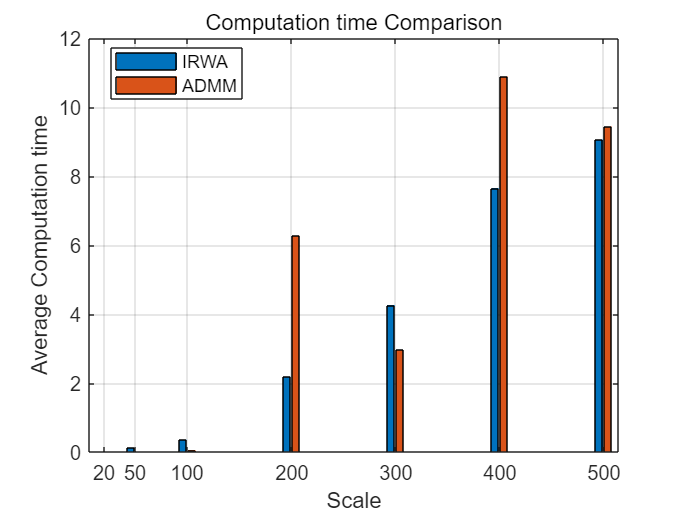


time_ADMM_500 = time_ADMM_500 / iterations;
time_IRWA_500 = time_IRWA_500 / iterations;
time_baseline_500 = time_baseline_500 / iterations;



problem_sizes = [20, 50, 100, 200, 300, 400, 500]; % 更新问题规模
time_IRWA = [time_IRWA_20, time_IRWA_50, time_IRWA_100, time_IRWA_200, time_IRWA_300, time_IRWA_400, time_IRWA_500];
time_ADMM = [time_ADMM_20, time_ADMM_50, time_ADMM_100, time_ADMM_200, time_ADMM_300, time_ADMM_400, time_ADMM_500];

% 绘制柱形图
figure;
bar(problem_sizes, [time_IRWA; time_ADMM]', 'grouped');
xlabel('Scale');
ylabel('Average Computation time');
title('Computation time Comparison');
legend('IRWA', 'ADMM', 'Location', 'best'); % 移动图例位置
grid on;

function x = QP_scaling_1(A1, A2, b1, b2, g, H)
    A = [A1; A2];
    b = [b1; b2];

    n = size(g, 1);
    m_eq = size(A1, 1);
    m_ineq = size(A2, 1);
    m = size(A, 1);
    epsilon = ones(m, 1);
    x = zeros(n, 1);
    eta = 0.9;
    gamma = 0;
    M = 100;
    prim_tol = 1e-6;
    dual_tol = 1e-6;
    max_iter = 4000;

    scale_eq = 1 / norm(A1, 'fro');
    scale_ineq = 1 / norm(A2, 'fro');  
    scaling_matrix = diag([scale_eq * ones(m_eq, 1); scale_ineq * ones(m_ineq, 1)]);

    A_scaled = scaling_matrix * A;
    b_scaled = scaling_matrix * b;

    for k = 1:max_iter
        Eq = A1 * x;
        Ineq = A2 * x;
        w = [Eq + b1; (max(Ineq, -b2) + b2)];

        w_scaled = scaling_matrix * w;
        w_scaled = (epsilon.^2 + w_scaled.^2).^(-0.5) + 1 ./ epsilon;
        W = diag(w_scaled);

        v = scaling_matrix * [b1; max(-Ineq, b2)];

        H_tilde = H + A_scaled' * W * A_scaled;
        g_tilde = g + A_scaled' * W * v;
        x_next = lsqminnorm(H_tilde, -g_tilde);

        % Step 2: Update relaxation vector
        q = A_scaled * (x_next - x);
        r = scaling_matrix * ((1 - v) .* (A_scaled * x + b_scaled));

        if all(abs(q) <= M * ((r.^2 + epsilon.^2).^(0.5 + gamma)))
            epsilon = epsilon * eta;
        end

        % Step 3: Check stopping criteria
        if norm(x_next - x) <= prim_tol && norm(epsilon) <= dual_tol
            x = x_next;
            break;
        end

        x = x_next;
    end
end

function x = ADMM_QP_1(A1,A2,b1,b2, q, P)
    % Import necessary utility functions
    [A,l,u] = standard_constraints(A2,-b2,A1,-b1);
    sigma = 1e-6;
    alpha = 1.6;
    n = size(P, 1);
    m = size(A, 1);
    x = zeros(n,1);
    y = zeros(m,1);
    z = zeros(m,1);
    rho = 0.1;
    prim_tol = 1e-4;
    dual_tol = 1e-6;
    max_iter = 100;
    if n<100
        inner_loop = 50;
    elseif n<1000
        inner_loop  = 200;
    else
        inner_loop = 500;
    end
    
    function rho_estimate = compute_rho()
        RHO_MIN = 1e-06;
        RHO_MAX=1;
        DIVISION_TOL = 1e-20;
        prim_res_norm = norm(z,1);
        temp_res_norm = norm(A*x,1); 
        prim_res_norm = max(prim_res_norm, temp_res_norm);
        prim_res = prim_res/(prim_res_norm + DIVISION_TOL);
        
        dual_res_norm = norm(q,1);
        temp_res_norm = norm(A'*y,1);
        dual_res_norm = max(dual_res_norm, temp_res_norm);
        temp_res_norm = norm(P*x,1);
        dual_res_norm = max(dual_res_norm, temp_res_norm);
        dual_res = dual_res/(dual_res_norm + DIVISION_TOL);
    
        rho_estimate = norm(rho * sqrt(prim_res / dual_res),1);
        rho_estimate = min(max(rho_estimate, RHO_MIN), RHO_MAX);
    end
    for i = 1: max_iter
        x_prev = x;
        for j = 1:inner_loop
            M = P + sigma * eye(n) + rho * (A'* A);
            b =  sigma* x - q + A'*(rho*z - y );
            x_tilde = conjgrad(M,b);
            z_tidle = A*x_tilde;
            x_next = alpha * x_tilde + (1 - alpha) * x;
            z_next = Pc(alpha * z_tidle + (1 - alpha) * z + 1 / rho * y, l, u);
            y = y + rho * (alpha * z_tidle + (1 - alpha) * z - z_next);
            z = z_next;
            prim_res = A*x-z;
            dual_res = P * x_next + q + A' * y;
    
            if norm(prim_res) <= prim_tol && norm(dual_res) <= dual_tol
                x = x_next;
                break;
            end
            if norm(x-x_next,2)<1e-5
                break
            end
            x_prev = x;
            x = x_next;
        end
        if norm(x-x_prev,2)<1e-5
            break
        end
        rho = compute_rho();
    end
end